# 1.Bode extraction

## 1.1.Load the data

load('Data.mat');
omega = log10(Data.omega);
magnitude = 20.*log10(Data.magnitude);
phase = Data.phase ;

## 1.2.Plot

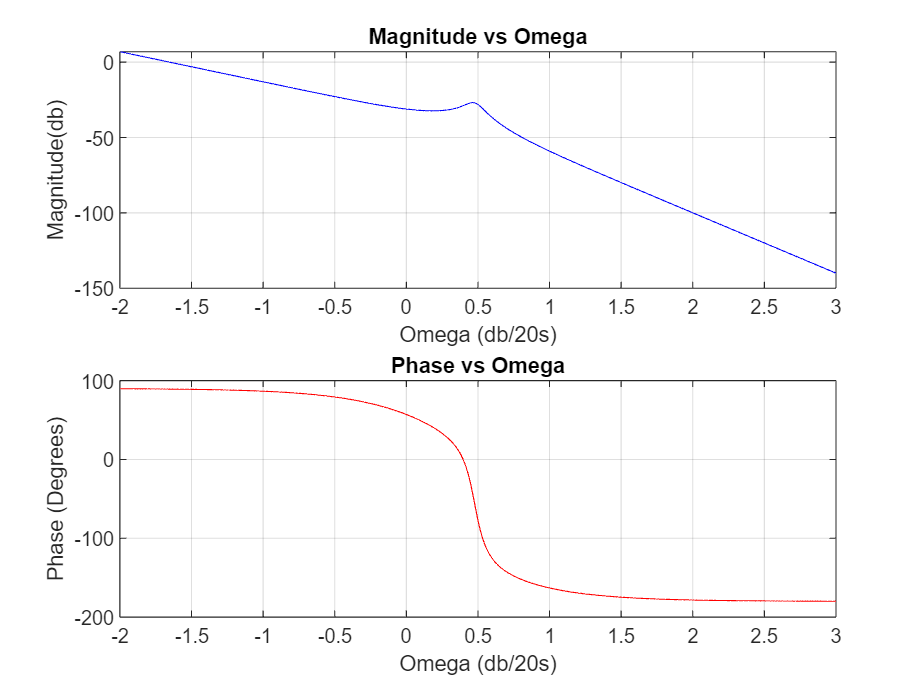

figure;
subplot(2,1,1);
plot(omega, magnitude, 'b');   % Plot Magnitude vs Omega
xlabel('Omega (db/20s)');
ylabel('Magnitude(db)');
title('Magnitude vs Omega');
grid on;
subplot(2,1,2);
plot(omega, phase, 'r');       % Plot Phase vs Omega
xlabel('Omega (db/20s)');
ylabel('Phase (Degrees)');
title('Phase vs Omega');
grid on;

# 2.System identification

## 2.1.System type

As the slope in the Magnitude part is -20dB/dec, we assume that we have a pole in the Origin so obviously the answer to step function should be "0" and the system is type 1.

## 2.2.System order

As explained in section 2.4 we have 3 poles so the system is from the third order.

## 2.3.System delay

To estimate the delay $\tau$, you can calculate the slope of the phase curve at different frequencies.

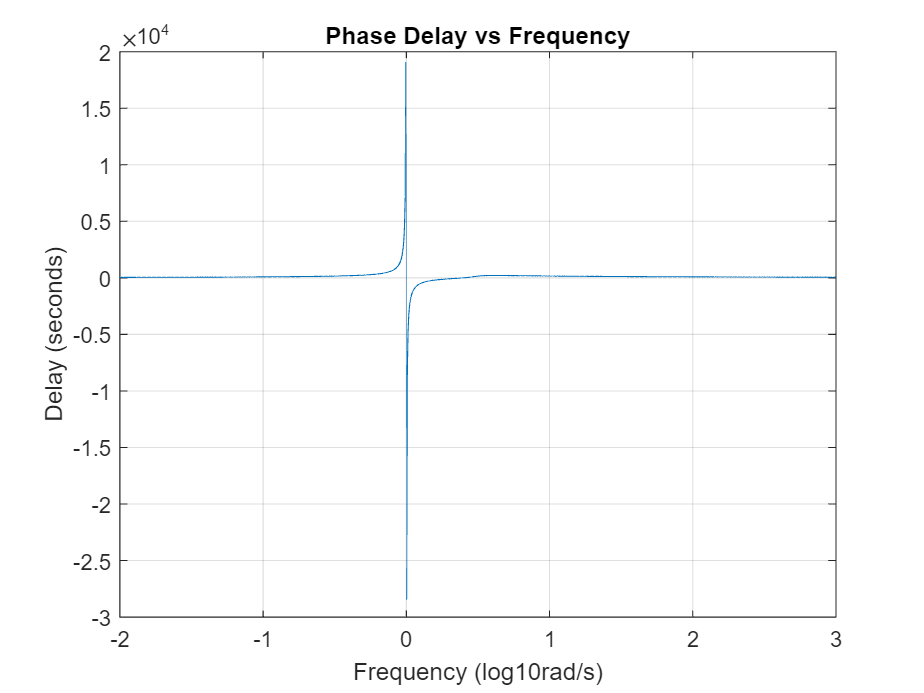

delay = -phase  ./ omega;  % Phase delay at each frequency (in seconds)

figure;
plot(omega,delay) % Plot delay vs frequency (log scale for omega)
xlabel('Frequency (log10rad/s)');
ylabel('Delay (seconds)');
grid on;
title('Phase Delay vs Frequency');

## 2.4.Minimum phase

As it can be seen in the Bode diagram, we start the magnitude with a -20dB/dec slope and a phase of 90 which shows that we have a "-s" and a second order func pole with positive middle coefficient and a zero at the same frequency, So it has a minimum phase zero.

# 3.Transfer function

The estimated transfer function is gonna be like the following

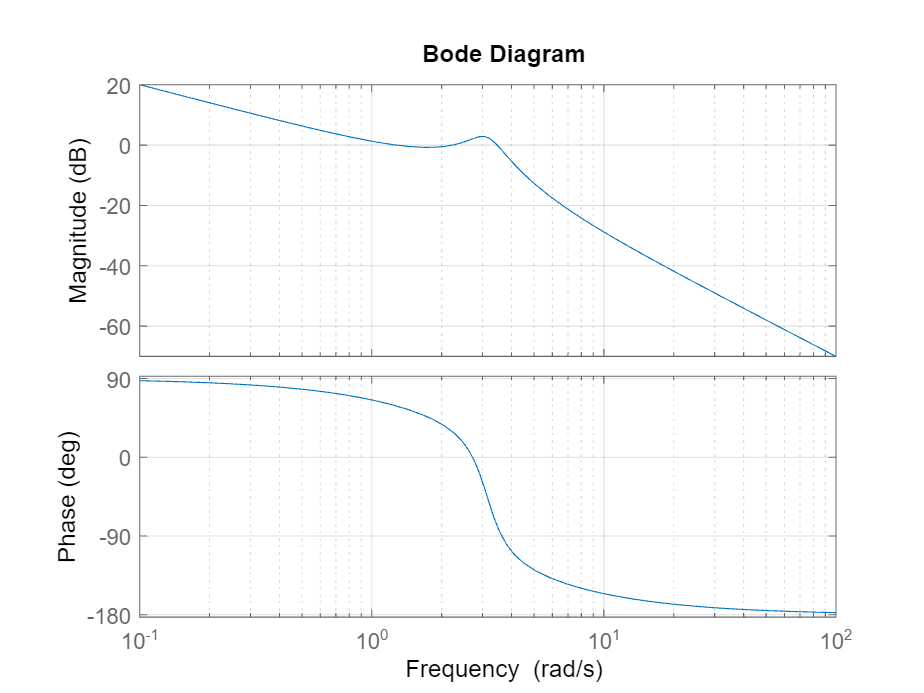

num = [1/pi -1];
den = conv([1/(pi^2) 1/(3*pi) 1], [1 0]);
sys = tf(num,den);
bode(sys);
grid on;

which actually looks the same as the upper expresion.

## 3.1.Optional first

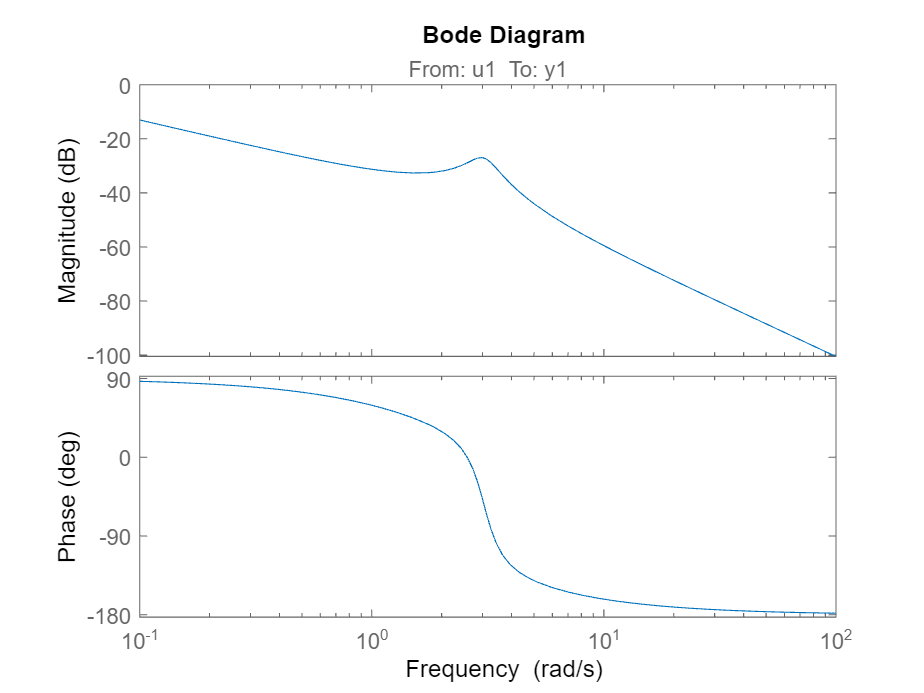

systemIdentification;
bode(tf1);

tf1

tf1 =
  From input "u1" to output "y1":
           0.09401 s - 0.2059
  -------------------------------------
  s^3 + 0.861 s^2 + 9.266 s - 8.868e-07
 
Name: tf1
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using TFEST on frequency response data "mydata".
Fit to estimation data: 99.82%                            
FPE: 7.3e-07, MSE: 7.196e-07                              
 
Model Properties


# 4.Ruth hurwitz

syms s;

% Define the characteristic equation
char_eq = (1/(pi^2)) * s^3 + (1/(3*pi)) * s^2 + 1 * s;

% Get the coefficients as a numeric vector
coeffs = double(sym2poly(char_eq));  % Ensure numeric values

% Compute the Routh array
routh_table = routh_hurwitz(coeffs);

% Display Routh-Hurwitz Table in Live Script
disp('Routh-Hurwitz Table:');

Routh-Hurwitz Table:


    0.1013    1.0000
    0.1061         0
    1.0000         0
         0         0



disp(routh_table);

I tried to do the computing completly on matlab but I couldnt figure it out, the computing goes on by writing the characteristic equation considering K and being close loop. It converts to $\frac{s^3 }{\pi^2 }+\frac{s^2 }{3\pi }+\left(1+k\right)s-k\pi$ which translates to the ruths tables first column to be $\frac{1}{\pi^2 }\;\;\;\frac{1}{3\pi }\;\;\;\left(1+4k\right)\;\;-k\pi$ which means that k is to be $-\frac{1}{4}<k<0$

# 5.Ruth locus analysis

## 5.1.Ploting

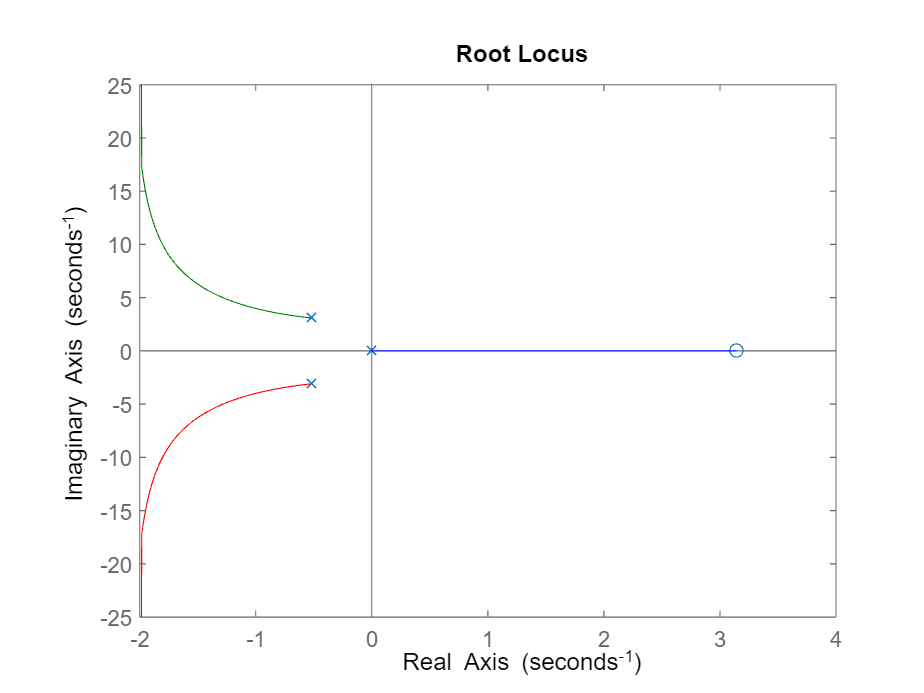

rlocus(sys);

As seen, we have a complete branch in the ORHP which means that we can't manage stablizing the system using only the k coefficient.

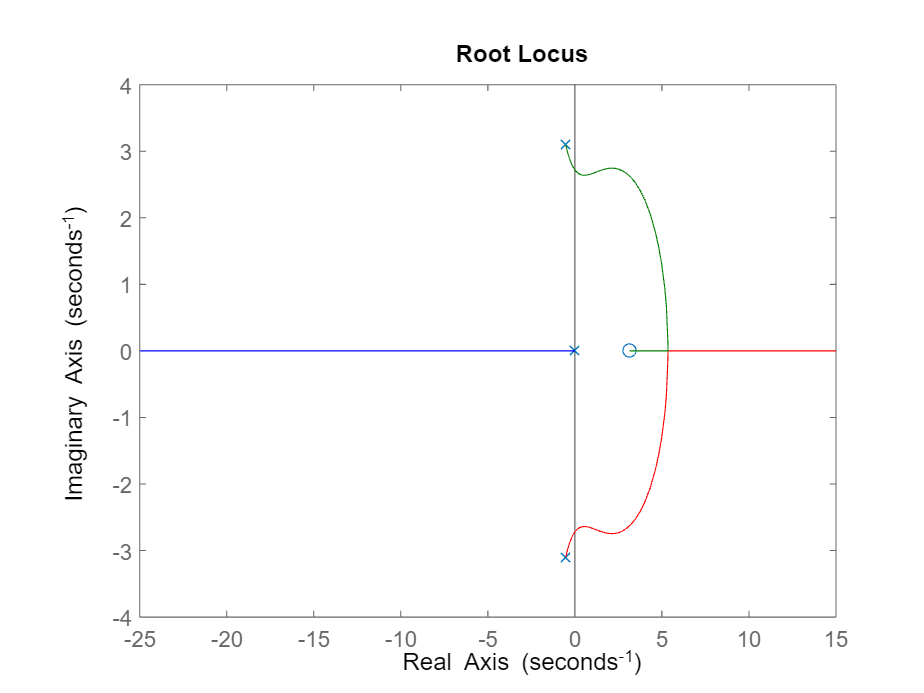

rlocus(-sys);

Working with the negative Ks, we have a really small gap in the branches to work with which actually matches what we saw in ruth's method.

## 5.2.Configure a PI or PD controller

We can add another minimum phase zero and another pole in the PLHP so that it leads to apearing a new branch moving from the OLHP to ORHP so that we find the chance to consider areas for K to bring all the poles in the OLHP so it shapes a PID.

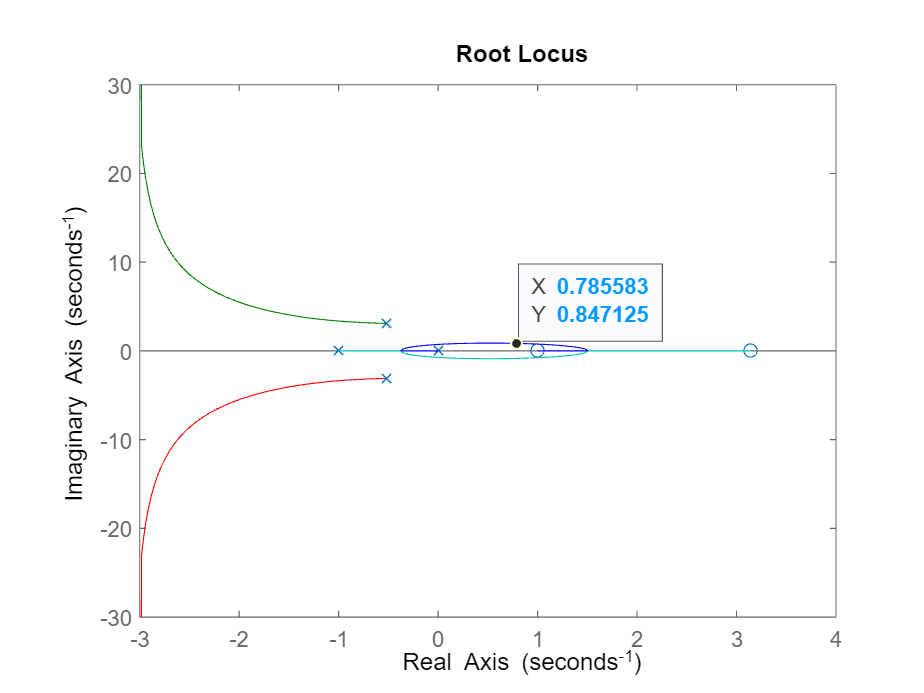

num = conv([1/pi -1] , [1 -1]);
den = conv([1/(pi^2) 1/(3*pi) 1], [1 1 0]);
sys_rc = tf(num,den);
rlocus(sys_rc);

As you see now we have a little area in positive Ks to bring all the poles in the OLHP and make the system stable.

# 6.Control overshoot

Our closed loop transfer function will be $\frac{{k\pi }^2 }{s^2 +\frac{\pi }{3}s+\left(k+1\right)\pi^2 }$ which is a shape of $\frac{{k\omega_n }^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }$ and as $M_p =e^{-\frac{\xi \pi }{\sqrt{1-\xi^2 }}}$ it concludes that $3\ldotp 96<\zeta <5\ldotp 8$ and settling time with a $\delta =2%$ is equal to $\frac{4}{\xi \omega_n }$ so we conclude that $\xi >\frac{4}{10\pi \sqrt{k+1}}$ and we can consider $-\frac{63}{64}>k>-\frac{3339}{3364}$ and we can find a k between these using an old rule :))) 


$$k=-\frac{63+3339}{64+3364}$$
 

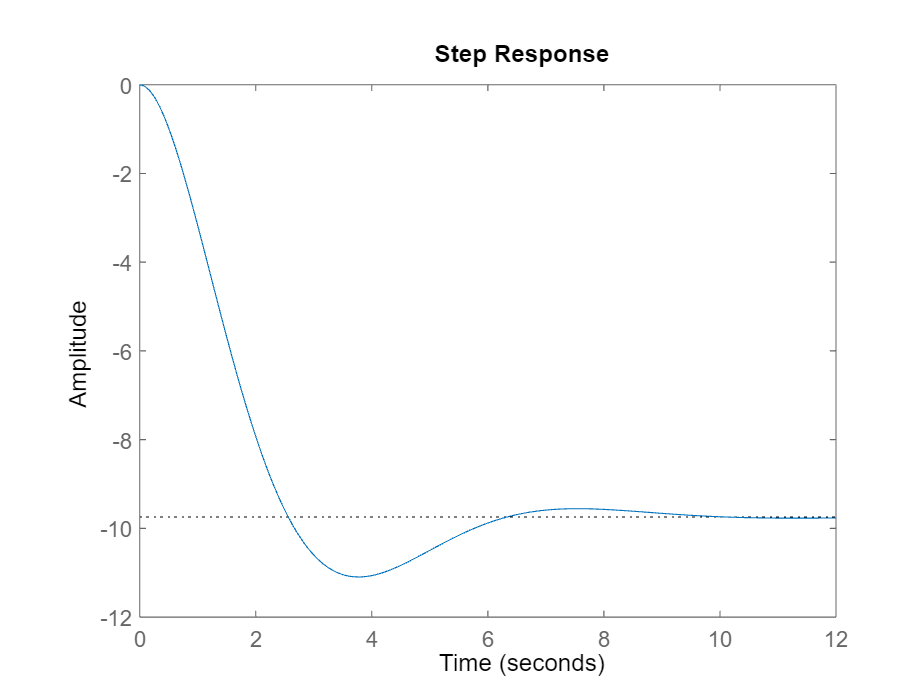

num = -9.432;
den = [1 pi/3 0.968];                 % a little help from instincs :)
sys_c = tf(num,den);
step(sys_c);

stepinfo(sys_c)

ans = struct with fields:
         RiseTime: 1.7318
    TransientTime: 5.8792
     SettlingTime: 5.8792
      SettlingMin: -11.0961
      SettlingMax: -8.9610
        Overshoot: 13.8785
       Undershoot: 0
             Peak: 11.0961
         PeakTime: 3.7819


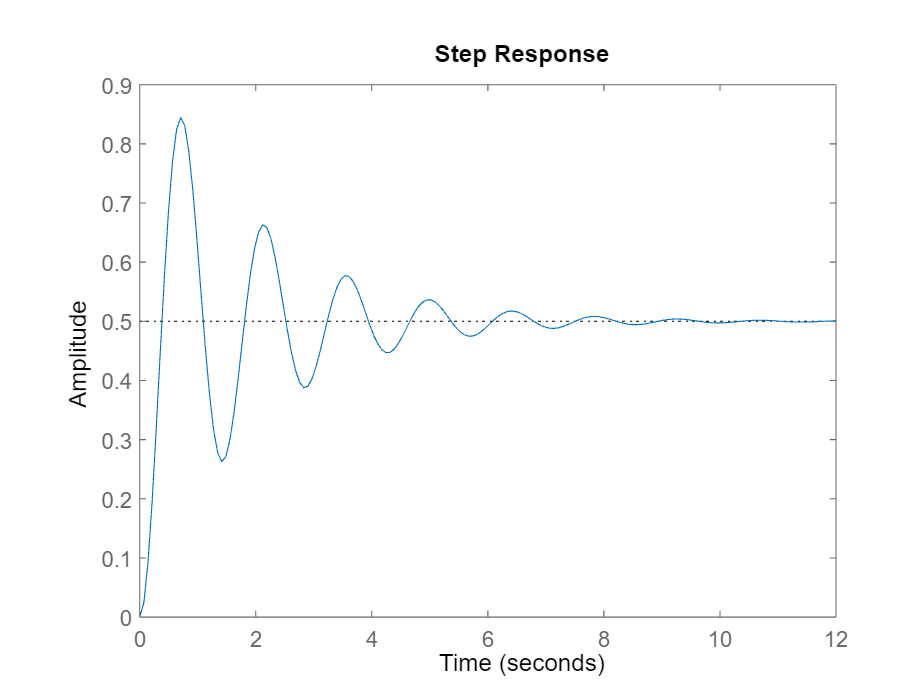

num = pi^2;
den = [1 pi/3 2*pi^2];
sys_uc = tf(num,den);
step(sys_uc);

stepinfo(sys_uc)

ans = struct with fields:
         RiseTime: 0.2575
    TransientTime: 7.2524
     SettlingTime: 7.2524
      SettlingMin: 0.2630
      SettlingMax: 0.8443
        Overshoot: 68.8609
       Undershoot: 0
             Peak: 0.8443
         PeakTime: 0.7071


# 7.Controller design

## 7.1.Maximum of 2% for $e_{\textrm{sr}}$

$\frac{1}{s}S\left(s\right)=\frac{1}{s^2 \left(1+L\left(s\right)\right)}$ so $y\left(s\right)=\frac{1}{s^3 \left(1+L\left(s\right)\right)}$ and the $e_{\textrm{sr}} =\lim_{s\longrightarrow 0} \frac{1}{s\left(1+\frac{s-\pi }{s\left(\frac{s^2 }{\pi^2 }+\frac{s}{3\pi }+1\right)}\right)}=-\frac{1}{\pi }=\frac{1}{k_v }<\frac{1}{50}$ so we need a $\frac{50}{\pi }$ gain to reach the wanted result.                 Also we add a zero at orgin.

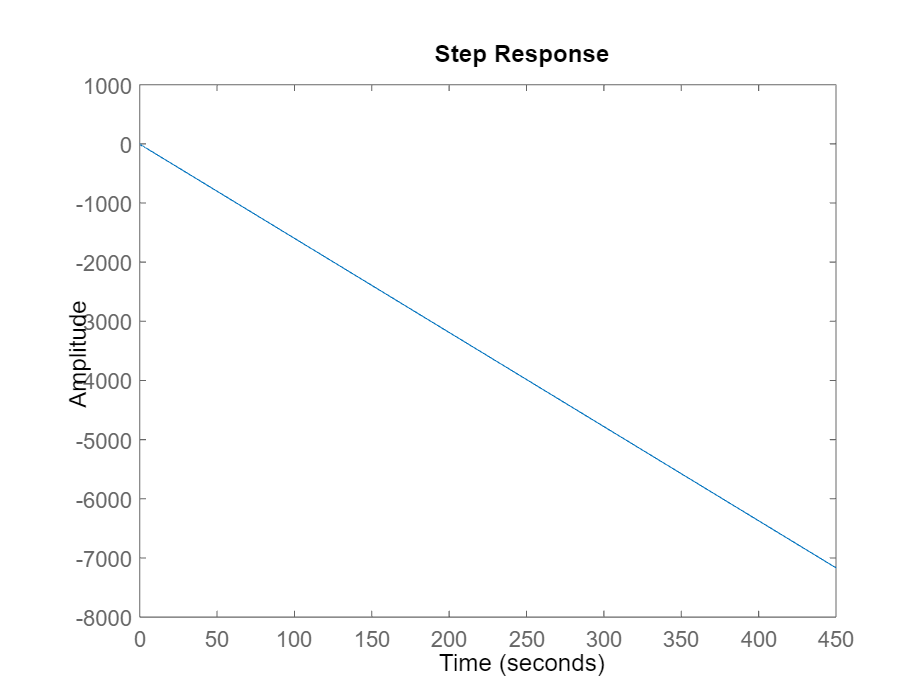

K = (50/pi) -1;
T = (1/25)*(((K/0.05)^2)-1)^0.5;
num = conv([T 50/pi] , [1/pi -1 0]);
den = conv([1/(pi^2) 1/(3*pi) 1] , [1 0 0]); %having ramp response is equal to adding
sys_fc = tf(num,den);                        %a pole at orgin then computing the step
step(sys_fc);                                %response.

Thanks for your attention!

Iman Bidi 40116503 Linear Control Final project

Winter of 2025